### Question 1

Consider a pillar made of two pieces of the same material (see figure). The first one is a truncated rectangular pyramid of height $h = 1.00$, with length sides $a=2$ and $c=2$ of the base and $b=1$ and also $c=2$ the lenght sides of the top. The second part is prismatic of volume of height $2h=2.00$. We suppose that the pillar is fixed at the base and only subjected to the gravity force without additional loads. We study the deformation of the pillar as a FEM 1D problem using a mesh of two elements, relating to the parts of the pillar. The pyramid basis is modelled by one linear element, while the prismatic part by one quadratic element as shown in the figure. In order to simplify the calculations we take $\omega = 3$as the spacific weight of the material and $E(x) = 1$ for the Young modulus.

                                                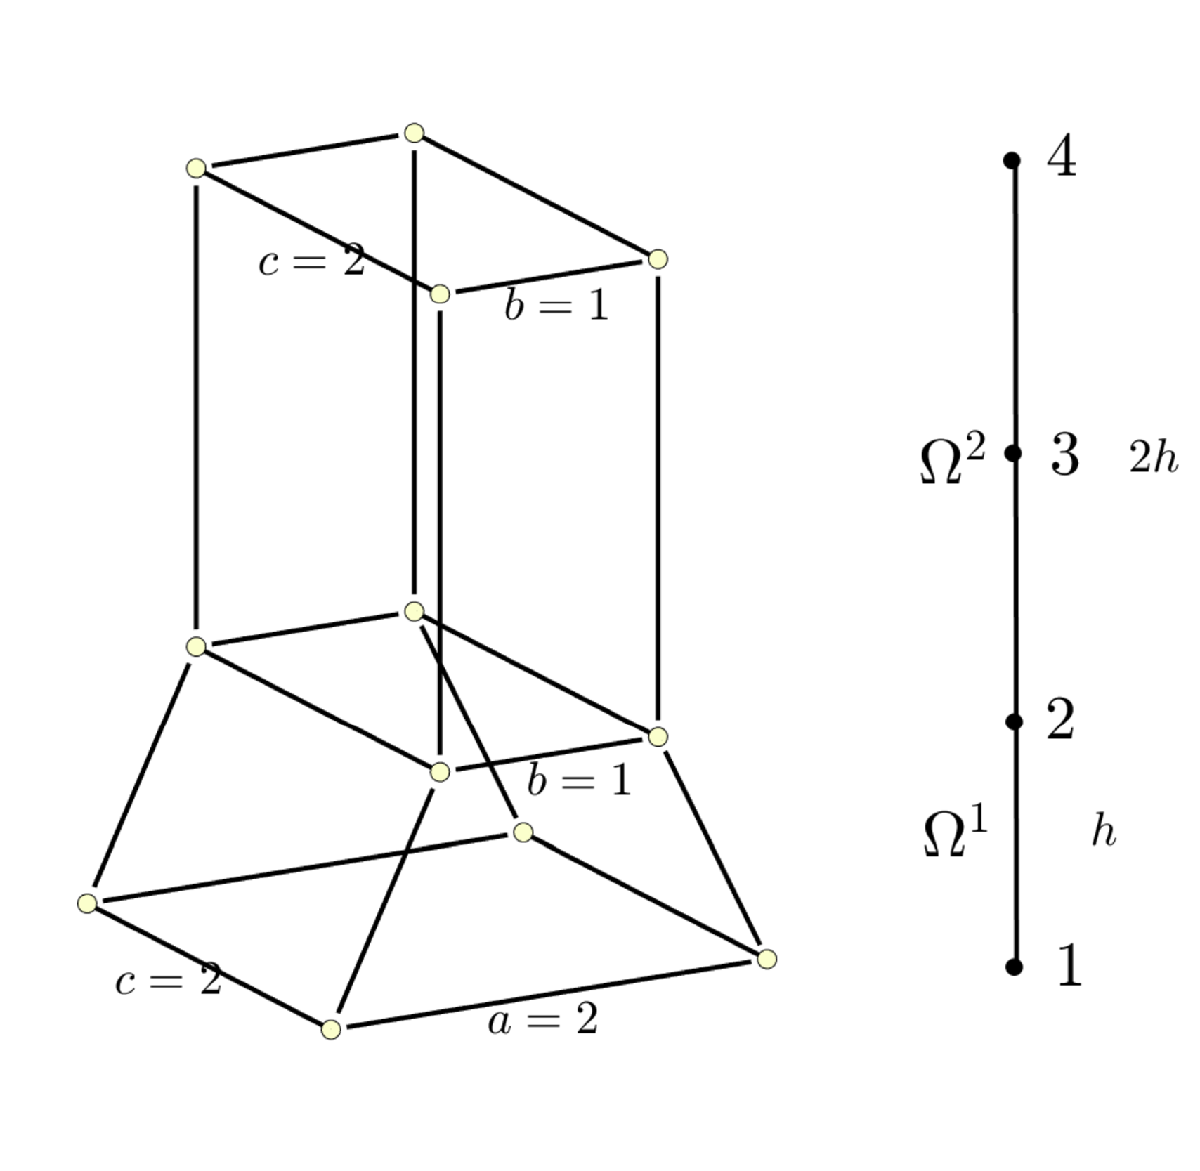

Asnwer the following questions:

#### Part a (2 points)

Let $\psi_{2}^{2}$ the second shape function of the quadratic element and $p=1.30$, a point inside there. The value of $\psi_{2}^{2}(p)$ is: 

*Solution.* The shape function $\psi_{2}^{2}$ is given by

            
$$\psi_{2}^{2}(x) = \frac{(x-1)(x-3)}{(2-1)(2-3)} =-(x-1)(x-3)$$


so, its value at the point $p=1.3$ is $\psi^{2}_{2}(1.3) = -(1.3-1)(1.3-3) = 0.3\times 1.7 = 0.51$.

syms x;
Psi2 = @(x) [(x-2).*(x-3)/2;-(x-1).*(x-3);(x-1).*(x-2)/2];
p = 1.3;
psi2P = Psi2(p);
fprintf('Psi 2 of elem 2 at p = %f: %.4e\n',p,psi2P(2))

Psi 2 of elem 2 at p = 1.300000: 5.1000e-01


#### Part b (2 points)

The value of the component $K_{21}^{1}$of the stiff local matrix of the element $\Omega^{1}$is:

*Solution.* On the one hand, the shape functions and their derivatives of the (linear) element $\Omega^{1}$, are given by

    
$$\begin{array}{ll}
\psi_{1}^{1} (x) = \frac{x-1}{0-1} = 1-x, &\displaystyle \frac{\mathrm{d}\psi_{1}^{1}}{\mathrm{d} x}(x)= -1,\\
\psi_{2}^{1}(x) = \frac{x-0}{1-0} = x, & \displaystyle \frac{\mathrm{d}\psi_{1}^{2}}{\mathrm{d} x}(x) = 1.
\end{array}$$


 On the other hand, it can be seen that the section area is given as a function of the height, $x$, by $A(x) = 2(2-x)$, $0\le x \le 1$. Therefore


$$K^{1}_{21} = \int_{x_{1}^{1}=0}^{x^{2}_{1} = h = 1} E A(x) \frac{\mathrm{d}\psi_{2}^{1}}{\mathrm{d} x}(x)\frac{\mathrm{d}\psi_{1}^{1}}{\mathrm{d} x}(x)\,\mathrm{d}x = 2\int_{0}^{1} (2-x) (1)(-1)\,\mathrm{d} x = 
-2\int_{0}^{1} (2-x)\,\mathrm{d} x -\left[\left(2x - \frac{x^{2}}{2}\right)\right]_{0}^{1} = -2\left(2 - \frac{1}{2}\right) = -\frac{6}{2} = -3
$$


Psi1 = @(x) [1-x; x];
A = @(x) 2*(2-x);
E = 1;
K1 = int(E*A(x)*diff(Psi1(x),x)*diff(Psi1(x),x)',0,1)

$$K1 = \left(\begin{array}{cc} 3 & -3\\ -3 & 3 \end{array}\right)$$

fprintf('K1(2,1) = %.4e\n',K1(2,1));

K1(2,1) = -3.0000e+00


#### Part c (2 points)

Knowing that the local vector force  of the element $\Omega^{1}$is $F^{1} = \left(-5.00, -4.00\right)$. The second component $F_{2}$of the assembled global vector force is:

*Solution.* The force due to the weight at the height $x$, $h = 1\le x\le H = 3h = 3$, $F(x)$, is given by,

    
$$W(x) = \int_{x}^{3h = 3} \omega A_{2}\,\mathrm{d} x \Longrightarrow f(x) = \frac{\mathrm{d} W}{\mathrm{d} x }(x) = -\omega A_{2} = -6,\qquad 1 \le x \le 3$$


(recall that $h = 1$, $A_{2} = b c = 2$, $\omega = 3$), where $A_{2}$ is the section area of the prismatic part. Moreover, the shape function $\psi_{1}^{2}$, is $\psi_{1}^{2} (x) = \frac{1}{2}(x-2)(x-3)$. Hence,


$$\begin{array}{rcl}
F^{2}_{1}\!\!\! &=&\!\!\! \int^{x^{2}_{3}}_{x^{2}_{1}} f(x)\;\psi^{2}_{1}(x)\,\mathrm{d} x = -6 \int^{3h = 3}_{h = 1} \frac{1}{2}(x-2)(x-3)\,\mathrm{d} x =
-3\int_{1}^{3} (x-2)(x-2-1)\,\mathrm{d} x = -3\int^{3}_{1} (x-2)^{2}\,\mathrm{d} x + 3\int^{3}_{1} (x-2)\,\mathrm{d} x \\
&\!\!=\!\!&
\left\{\begin{array}{l}
   \text{Change of variables:}\\
   t = x - 2: \mathrm{d} t  = \mathrm{d} x,\\
  x = 1\Longrightarrow t = -1,\\
 x = 3\Longrightarrow t = 1.\end{array}\right\} = -\int^{1}_{-1} t^{2}\,\mathrm{d} t + 3\int^{1}_{-1} t\,\mathrm{d} t 
= -6 \int^{1}_{0} t^{2}\,\mathrm{d} t = - 6 \left[\frac{t^{3}}{3}\right]^{1}_{0} = -2.
\end{array}$$


Therefore, the second component of the global load vector, $F_{2}$ is


$$F_{2} = F^{1}_{2} + F^{2}_{1} = -4 - 2 = -6.$$


c = 2;
b = 1;
omega = 3;
A2 = c*b;                 %Second element's section area
f2 = -omega*A2;           %Weight per unit length at the second element
F1 = [-5.0;-4.0];         %Local load vector of the first element
F = zeros(4,1);
F2 = int(f2*Psi2(x),1,3); %Local load vector of the second element
F(1:2) = F1;
F(2:4) = F(2:4) + F2

F =       -5       
      -6       
      -8       
      -2       


fprintf('F(2) = %.4e\n',F(2)) %second component of the global vector

F(2) = -6.0000e+00


#### Part d (2 punts)

Knowing that $U_{3} = -\frac{59}{6}$, $U_{4} = -\frac{34}{3}$are solutions of the assembled global system . The value of $U_{2}$ is:

*Solution. *The first two equations of the assembled system are,

    
$$\frac{1}{3}\left(\begin{array}{rrrr}
-9 & -9 & 0 & 0\\
-9 & 16 & -8 & 1\end{array}\right) \left(\begin{array}{c} 
U_{1} \\ U_{2} \\ U_{3} \\ U_{4}\end{array}\right) = 
\left(\begin{array}{c} 
F_{1}  \\ F_{2}\end{array}\right) +
\left(\begin{array}{c}
Q_{1}\\
Q_{2}
\end{array}
\right)$$
 

 We know that the last two components of the soluiton are$U_{3} = -\frac{59}{6}$, $U_{4} = -\frac{34}{3}$. Furthermore, from the boundary conditons we also know that $Q_{2} = 0$ (no point loads are applied) and that$U_{1} = 0$ (the column is fixed at its basis); so $U_{2}$ can be isolated from tthe second equation. Hence,


$$U_{2} = \frac{1}{16} \left(3 F_{2}  + 3Q_{2} + 9 U_{1} + 8U_{3} - U_{4} \right) = \frac{1}{16}\left(-18 - 8\times\frac{59}{6} + \frac{34}{3}\right) = \frac{-290+34}{3\times 16} = -\frac{256}{3\times 16} = - \frac{2^{8}}{3\times 2^{4}} = - \frac{16}{3} = -5.3333\cdots$$



K2 = A2*E*int(diff(Psi2(x),x)*diff(Psi2(x),x)',1,3) %Local stiffness matrix of element Omega2

$$K2 = \left(\begin{array}{ccc} \frac{7}{3} & -\frac{8}{3} & \frac{1}{3}\\ -\frac{8}{3} & \frac{16}{3} & -\frac{8}{3}\\ \frac{1}{3} & -\frac{8}{3} & \frac{7}{3} \end{array}\right)$$

K = zeros(4);
Q = zeros(4,1);
K(1:2,1:2) = K1;
format rational
K(2:4,2:4) = K(2:4,2:4) + K2 %global stifness matrix

K =        3             -3              0              0       
      -3             16/3           -8/3            1/3     
       0             -8/3           16/3           -8/3     
       0              1/3           -8/3            7/3     


u = zeros(4,1);

fixedNods = 1;
freeNods = setdiff(1:4,fixedNods);

%set the boundary conditons, B.C.
%Natural B.C.

Q(freeNods)=0; 

%Essential B.C.
u(1)=0; 
fixedNods = [fixedNods, 3, 4];
freeNods = setdiff(1:4,fixedNods);
u(fixedNods)=[u(1);-59/6;-34/3];
Fm = F(freeNods) + Q(freeNods) - K(freeNods,fixedNods)*u(fixedNods)

Fm =     -256/9     


Km = K(freeNods,freeNods);
um = Km\Fm

um =      -16/3     


u(freeNods)=um

u =        0       
     -16/3     
     -59/6     
     -34/3     


u(2) %2nd Component of the solution

ans =      -16/3     


fprintf('u(2) = %.4e\n',u(2))

u(2) = -5.3333e+00


#### Part e (2 points)

The value of the reaction force $Q_{1}$:

*Solution. *We can get $Q_{2}$ from the first equaiton. Indeed:


$$Q_{1} = \frac{1}{3}\left(9 U_{1} - 9 U_{2} + 0 U_{3} + 0 U_{4}\right) - F_{1} = \frac{1}{3}\left(0 - 9 \times \left(-\frac{16}{3} \right) + 0 + 0\right) + 5 = 16 + 5 = 21.$$


Q = K*u - F; %Post process
fprintf('Q(1) = %.4e\n',Q(1)); %First component of Q (= reaction forces at node 1)

Q(1) = 2.1000e+01
